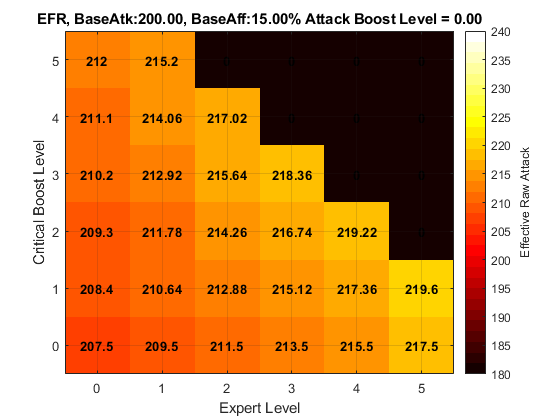

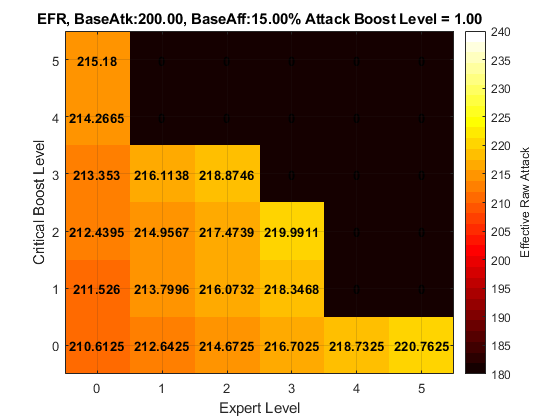

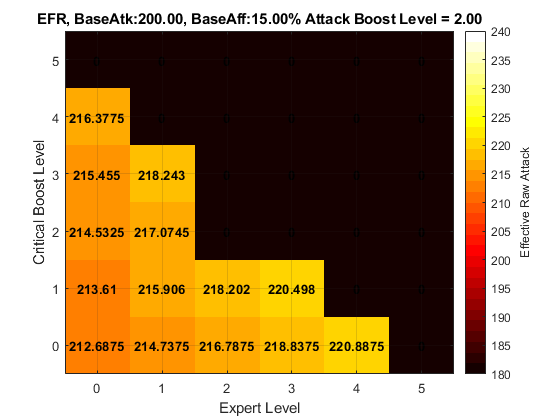

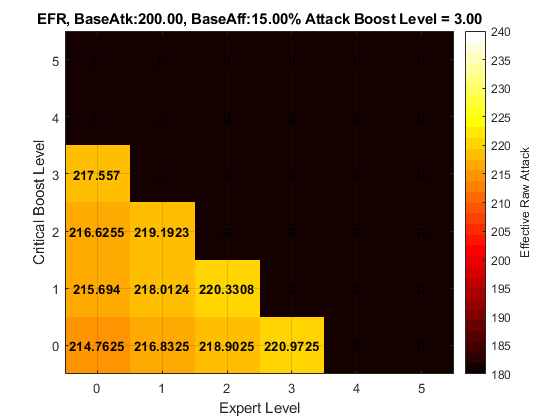

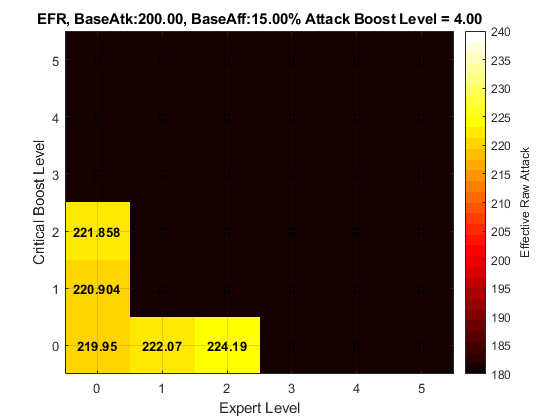

clear;
baseattack = 200;
baseaffinity = 15;
weapon_slots = [1;1;1]; % 3 level 3 slots

Aeq = ones(1,9);
Beq = 3;

% v is [Attack Boost Level; Expert Level; Crit Boost Level]
EVdWrapper = @(v) EVd(WeaponStats([baseattack;baseaffinity;weapon_slots;v]));

atk_bounds = [0, 5];
exp_bounds = [0, 5];
crit_bounds = [0, 5];   

nFrames = 5;

vec_atk = 0:1:5;
vec_exp = 0:1:5;
vec_crit = 0:1:5;

efr_col_palette = hot(32);

efrlb = baseattack - 0.1*baseattack;
efrub = 1.2*baseattack;
vec_colorbar_domain = efrlb:5:efrub;
vec_colorbar_bounds = [efrlb efrub];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% EFR t -> True Raw Attack %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[nEXP, nCRIT] = meshgrid(vec_exp, vec_crit);
maxefr = 0;
maxatkgems = 0;
maxexpgems = 0;
maxcritgems = 0;

for idx = 1:nFrames
    hfnEFR = arrayfun(@(nExp, nCrit) EVdWrapper([vec_atk(idx); nExp; nCrit]), nEXP, nCRIT);
    maxdmg = ceil(max(hfnEFR(:)));

    imagesc(vec_exp, vec_crit, hfnEFR);
    grid(gca, 'on');
    set(gca, 'YDir', 'normal');
    clim(vec_colorbar_bounds);
    colormap(efr_col_palette);

    hColBar = colorbar;
    hColBar.Ticks = vec_colorbar_domain;
    ylabel(hColBar, 'Effective Raw Attack');


    xlabel('Expert Level');
    ylabel('Critical Boost Level');
    xticks(0:1:5);    
    yticks(0:1:5);

    title(sprintf('EFR, BaseAtk:%.2f, BaseAff:%.2f%% Attack Boost Level = %.2f', baseattack, baseaffinity, vec_atk(idx)));

    for row = 1:6
        for col = 1:6
            value = hfnEFR(row, col);
            text(col - 1, row - 1, num2str(value), ...
                'Color', 'Black', 'FontWeight', 'bold', ...
                'HorizontalAlignment', 'center');
        end
    end

    figure;
    drawnow;
    pause(0.1);
end